% Standard form QP example

randn('state', 0);
rand('state', 0);

n = 3;

% generate a well-conditioned positive definite matrix
% (for faster convergence)
P = rand(n);
P = P + P';
[V D] = eig(P);
P = V*diag(1+rand(n,1))*V';

q = randn(n,1);
r = randn(1);

l = randn(n,1);
u = randn(n,1);
lb = min(l,u);
ub = max(l,u);
%Solve problem
[x history] = quadprog(P, q, r, lb, ub, 1.0, 1.0);

iter	    r norm	   eps pri	    s norm	  eps dual	 objective
  1	    0.3194	    0.0067	    0.6513	    0.0034	     -0.49
  2	    0.1289	    0.0089	    0.2323	    0.0046	     -0.53
  3	    0.0773	    0.0098	    0.0870	    0.0054	     -0.52
  4	    0.0462	    0.0101	    0.0324	    0.0059	     -0.50
  5	    0.0275	    0.0102	    0.0120	    0.0061	     -0.49
  6	    0.0163	    0.0103	    0.0044	    0.0063	     -0.48
  7	    0.0097	    0.0103	    0.0016	    0.0064	     -0.48
Elapsed time is 0.017696 seconds.


x

x =    -0.0376
    0.9961
    0.1746


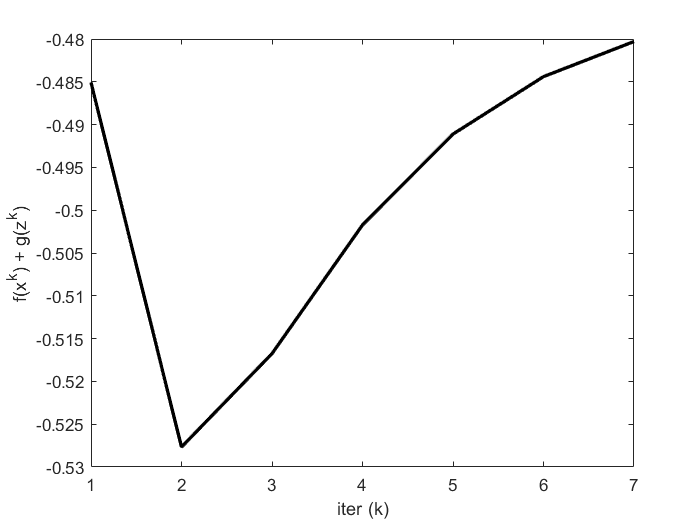


K = length(history.objval);

h = figure;
plot(1:K, history.objval, 'k', 'MarkerSize', 10, 'LineWidth', 2);
ylabel('f(x^k) + g(z^k)'); xlabel('iter (k)');

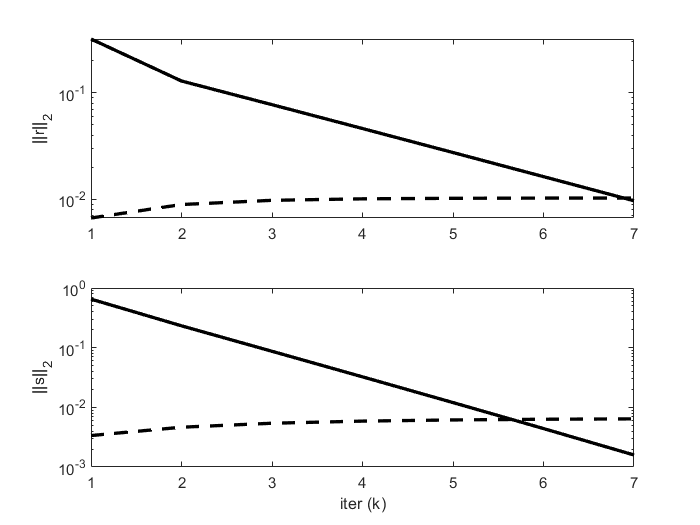


g = figure;
subplot(2,1,1);
semilogy(1:K, max(1e-8, history.r_norm), 'k', ...
    1:K, history.eps_pri, 'k--',  'LineWidth', 2);
ylabel('||r||_2');

subplot(2,1,2);
semilogy(1:K, max(1e-8, history.s_norm), 'k', ...
    1:K, history.eps_dual, 'k--', 'LineWidth', 2);
ylabel('||s||_2'); xlabel('iter (k)');

function [z, history] = quadprog(P, q, r, lb, ub, rho, alpha)
% quadprog  Solve standard form box-constrained QP via ADMM
%
% [x, history] = quadprog(P, q, r, lb, ub, rho, alpha)
%
% Solves the following problem via ADMM:
%
%   minimize     (1/2)*x'*P*x + q'*x + r
%   subject to   lb <= x <= ub
%
% The solution is returned in the vector x.
%
% history is a structure that contains the objective value, the primal and
% dual residual norms, and the tolerances for the primal and dual residual
% norms at each iteration.
%
% rho is the augmented Lagrangian parameter.
%
% alpha is the over-relaxation parameter (typical values for alpha are
% between 1.0 and 1.8).
%
%
% More information can be found in the paper linked at:
% http://www.stanford.edu/~boyd/papers/distr_opt_stat_learning_admm.html
%

t_start = tic;
%Global constants and defaults
QUIET    = 0;
MAX_ITER = 1000;
ABSTOL   = 1e-4;
RELTOL   = 1e-2;
%Data preprocessing
n = size(P,1);
%ADMM solver
x = zeros(n,1);
z = zeros(n,1);
u = zeros(n,1);

if ~QUIET
    fprintf('%3s\t%10s\t%10s\t%10s\t%10s\t%10s\n', 'iter', ...
      'r norm', 'eps pri', 's norm', 'eps dual', 'objective');
end

for k = 1:MAX_ITER

    if k > 1
        x = R \ (R' \ (rho*(z - u) - q));
    else
        R = chol(P + rho*eye(n));
        x = R \ (R' \ (rho*(z - u) - q));
    end

    % z-update with relaxation
    zold = z;
    x_hat = alpha*x +(1-alpha)*zold;
    z = min(ub, max(lb, x_hat + u));

    % u-update
    u = u + (x_hat - z);

    % diagnostics, reporting, termination checks
    history.objval(k)  = objective(P, q, r, x);

    history.r_norm(k)  = norm(x - z);
    history.s_norm(k)  = norm(-rho*(z - zold));

    history.eps_pri(k) = sqrt(n)*ABSTOL + RELTOL*max(norm(x), norm(-z));
    history.eps_dual(k)= sqrt(n)*ABSTOL + RELTOL*norm(rho*u);

    if ~QUIET
        fprintf('%3d\t%10.4f\t%10.4f\t%10.4f\t%10.4f\t%10.2f\n', k, ...
            history.r_norm(k), history.eps_pri(k), ...
            history.s_norm(k), history.eps_dual(k), history.objval(k));
    end

    if (history.r_norm(k) < history.eps_pri(k) && ...
       history.s_norm(k) < history.eps_dual(k))
         break;
    end
end

if ~QUIET
    toc(t_start);
end
end

function obj = objective(P, q, r, x)
    obj = 0.5*x'*P*x + q'*x + r;
end